phaseContrastImageProcessingTest2ys

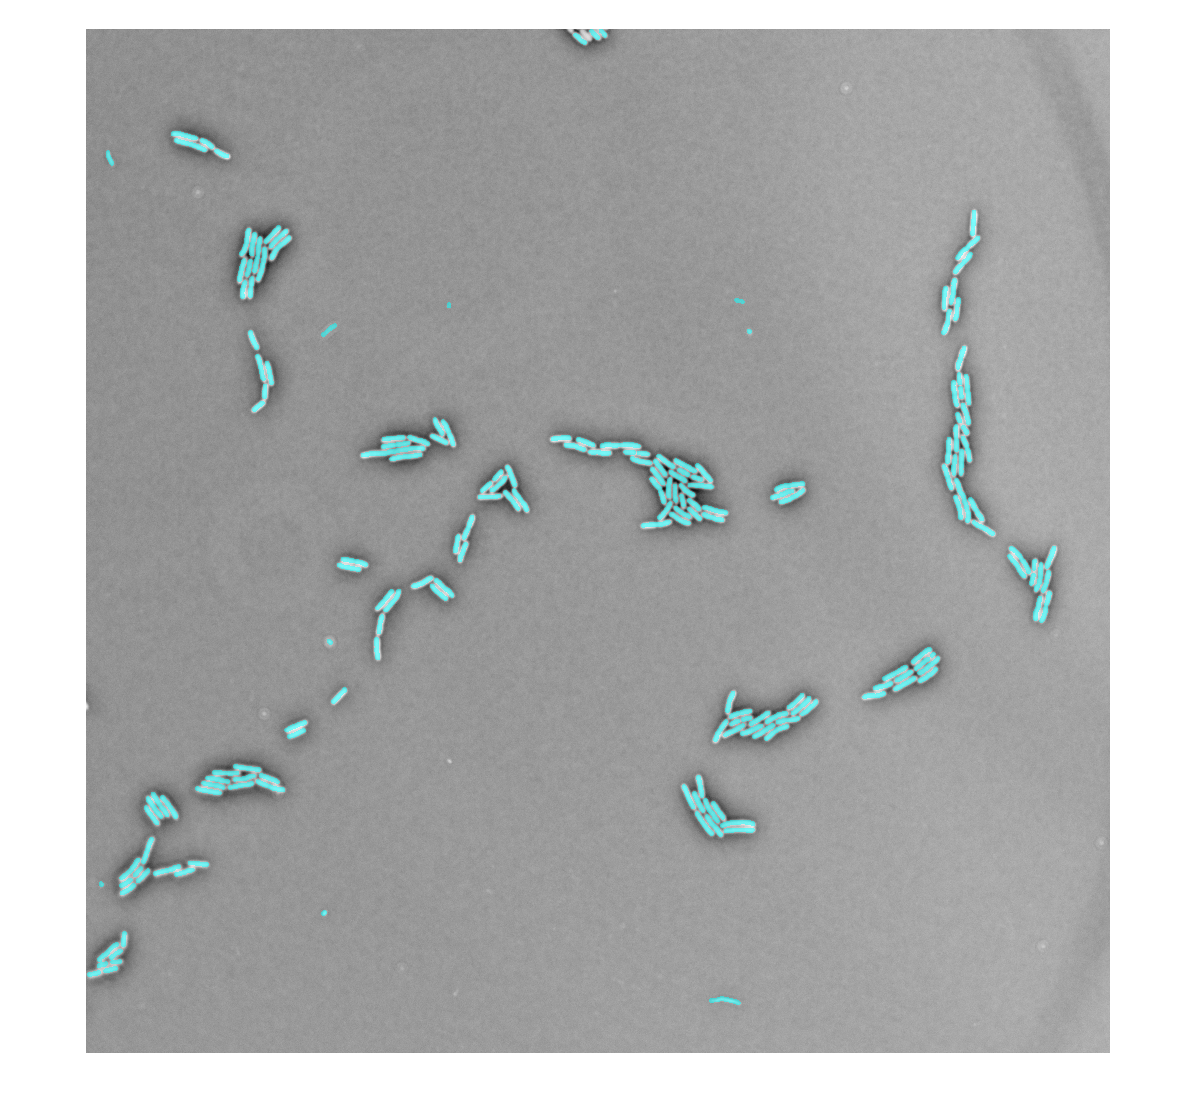

I0 = BF_3_MMStack_Default_ome;
% convert 8 bit image
I = uint8(double(I0-min(I0(:)))/double(max(I0(:))-min(I0(:)))*255);

I1 = 255 - I;

I2 = imsubtract(I1,I);

areaThreshold=100;
edgeFilter=(ones(5,5)).*-1;edgeFilter(3,3)=24;%created edgefilter

I2 = imgaussfilt(I2, 2);

I2 = imfilter(I2,edgeFilter);
% edgefilter后会产生一个2个pixel亮的边框
I_border = ones(2048,2048)*255; I_border(3:2046,3:2046) = 0;
I_border =uint8(I_border);
I2 = imsubtract(I2,I_border);

I3 = imgaussfilt(I2,2);

% I3_imadjust = imadjust(I3);
% I3_histeq = histeq(I3);
% I3_adapthisteq = adapthisteq(I3);
% montage({I3,I3_imadjust,I3_histeq,I3_adapthisteq},'Size',[1 4])
[Iobr] = cleanupImageUsingReconstuction(I3);

tempBW = edge((Iobr),'log');
tempBW = imclearborder(tempBW);
tempBW=imfill( tempBW,'holes');
se = strel('disk',2);
%     tempBW = imopen( tempBW, ones(2,2));
tempBW = imopen( tempBW, se);
tempBW = bwareaopen( tempBW, areaThreshold);


tempBW=imopen(tempBW,strel('disk',2));
tempBW=imopen(tempBW,ones(3));
tempBW=bwmorph(tempBW,'open');

tempImage = tempBW;
tempImage=imerode(tempImage,ones(4));%腐蚀进行分割
tempImage = bwareaopen(tempImage, 5);%删除小的零星的pixel
skel = bwmorph(tempImage,'skel',Inf);%获取骨架
E = bwmorph(skel, 'endpoints');
skel = skel&(~E); %删除endpoint 要不膨胀会连在一起
E = bwmorph(skel, 'endpoints');
skel = skel&(~E); %删除两次
%重组细菌
se = strel('disk',5);
bwSegNew = imdilate(skel,se);
bwSegNew=imfill( bwSegNew,'holes');

% overlay1 = imoverlay(I, bwSegNew, [.3 1 .3]);
% imshow(overlay1)
imshow(labeloverlay(I1, bwSegNew))